Parameter

% 10 rpm , Torque 3 N.m at O2
theta2 = sym('theta_2');   theta3 = sym('theta_3');   theta4 = sym('theta_4');
theta5 = sym('theta_5');   theta6 = sym('theta_6');
Dxs = sym('D_x');          Dys = sym('D_y');
% จุดยึดบนแผ่นโครง (mm) ตามแบบ : O1 - O2 ห่างกัน 45 , O2 ขาหน้า - O2 ขาหลัง ห่างกัน 180 , O3 อยู่เหนือ O2 45
O1_x_f = -45;   O2_x_f =   0;   O3_x_f =   0;      % ขาหน้า (_f)
O1_x_r = 225;   O2_x_r = 180;   O3_x_r = 180;      % ขาหลัง (_r)
O1_y = 0;       O2_y = 0;       O3_y = 45;
O3C = 40;   O1A = 25;   O2B = 20;   BA = 45;   AD = 40;   DC = 65;   DF = 70;
bend = 120*pi/180;
q0   = 105*pi/180;
rpm  = 10;    rot = -1;
omega4 = rot*2*pi*rpm/60;
T  = 60/rpm;
Torque = 3;
th      = q0 + rot*deg2rad(0:4:360);
th_st_f = deg2rad(78.13 + rot*(-90:3:90));
th_st_r = deg2rad(101.87 + rot*(-90:3:90));

Equation

%ขาหน้า
Bx_f = O2_x_f + O2B*cos(theta4);         By_f = O2_y + O2B*sin(theta4);
Ax_f = O1_x_f + O1A*cos(theta3);         Ay_f = O1_y + O1A*sin(theta3);
Dx_f = Bx_f + (BA+AD)*cos(theta5);       Dy_f = By_f + (BA+AD)*sin(theta5);
Cx_f = O3_x_f + O3C*cos(theta2);         Cy_f = O3_y + O3C*sin(theta2);
Fx_f = Dx_f + DF*cos(theta6-bend);       Fy_f = Dy_f + DF*sin(theta6-bend);
eq1_f = Ax_f == Bx_f + BA*cos(theta5);     eq2_f = Ay_f == By_f + BA*sin(theta5);
eq3_f = Cx_f == Dxs + DC*cos(theta6);    eq4_f = Cy_f == Dys + DC*sin(theta6);
sol1_f = solve([eq1_f eq2_f],[theta3 theta5]);
sol2_f = solve([eq3_f eq4_f],[theta2 theta6]);
[~,k1_f] = max(real(double(subs(sin(sol1_f.theta_3),theta4,q0))));
theta3_sol_f = sol1_f.theta_3(k1_f);       theta5_sol_f = sol1_f.theta_5(k1_f);
DxNew_f = subs(Dx_f,theta5,theta5_sol_f);  DyNew_f = subs(Dy_f,theta5,theta5_sol_f);
[~,k2_f] = max(real(double(subs(sin(sol2_f.theta_2),[Dxs Dys],subs([DxNew_f DyNew_f],theta4,q0)))));
theta2_sol_f = sol2_f.theta_2(k2_f);       theta6_sol_f = sol2_f.theta_6(k2_f);
S_f = @(s) subs(s,[theta2 theta3 theta5 theta6],[theta2_sol_f theta3_sol_f theta5_sol_f theta6_sol_f]);
AxNew_f = S_f(Ax_f);   AyNew_f = S_f(Ay_f);
CxNew_f = S_f(Cx_f);   CyNew_f = S_f(Cy_f);
FxNew_f = S_f(Fx_f);   FyNew_f = S_f(Fy_f);
Dxn_f = @(a) real(double(subs(DxNew_f,theta4,a)));
Dyn_f = @(a) real(double(subs(DyNew_f,theta4,a)));
N_f   = @(G,a) real(double(subs(G,{theta4,Dxs,Dys},{a,Dxn_f(a),Dyn_f(a)})));
%ขาหลัง
Bx_r = O2_x_r + O2B*cos(theta4);         By_r = O2_y + O2B*sin(theta4);
Ax_r = O1_x_r + O1A*cos(theta3);         Ay_r = O1_y + O1A*sin(theta3);
Dx_r = Bx_r + (BA+AD)*cos(theta5);       Dy_r = By_r + (BA+AD)*sin(theta5);
Cx_r = O3_x_r + O3C*cos(theta2);         Cy_r = O3_y + O3C*sin(theta2);
Fx_r = Dx_r + DF*cos(theta6+bend);       Fy_r = Dy_r + DF*sin(theta6+bend);
eq1_r = Ax_r == Bx_r + BA*cos(theta5);     eq2_r = Ay_r == By_r + BA*sin(theta5);
eq3_r = Cx_r == Dxs + DC*cos(theta6);    eq4_r = Cy_r == Dys + DC*sin(theta6);
sol1_r = solve([eq1_r eq2_r],[theta3 theta5]);
sol2_r = solve([eq3_r eq4_r],[theta2 theta6]);
[~,k1_r] = max(real(double(subs(sin(sol1_r.theta_3),theta4,q0))));
theta3_sol_r = sol1_r.theta_3(k1_r);       theta5_sol_r = sol1_r.theta_5(k1_r);
DxNew_r = subs(Dx_r,theta5,theta5_sol_r);  DyNew_r = subs(Dy_r,theta5,theta5_sol_r);
[~,k2_r] = max(real(double(subs(sin(sol2_r.theta_2),[Dxs Dys],subs([DxNew_r DyNew_r],theta4,q0)))));
theta2_sol_r = sol2_r.theta_2(k2_r);       theta6_sol_r = sol2_r.theta_6(k2_r);
S_r = @(s) subs(s,[theta2 theta3 theta5 theta6],[theta2_sol_r theta3_sol_r theta5_sol_r theta6_sol_r]);
AxNew_r = S_r(Ax_r);   AyNew_r = S_r(Ay_r);
CxNew_r = S_r(Cx_r);   CyNew_r = S_r(Cy_r);
FxNew_r = S_r(Fx_r);   FyNew_r = S_r(Fy_r);
Dxn_r = @(a) real(double(subs(DxNew_r,theta4,a)));
Dyn_r = @(a) real(double(subs(DyNew_r,theta4,a)));
N_r   = @(G,a) real(double(subs(G,{theta4,Dxs,Dys},{a,Dxn_r(a),Dyn_r(a)})));

Animation

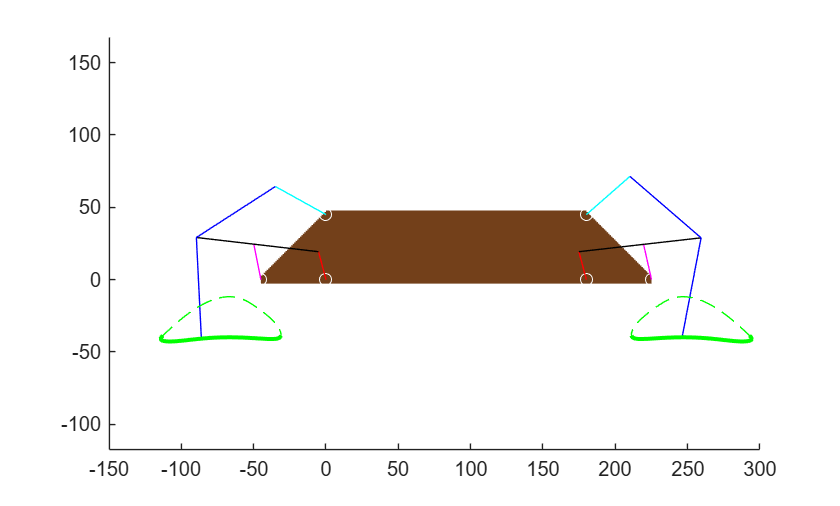

th4 = @(t) q0 + omega4*t;
h_link4_f = @(t) plot([O2_x_f N_f(Bx_f,th4(t))],[O2_y N_f(By_f,th4(t))],"-r");
h_link3_f = @(t) plot([O1_x_f N_f(AxNew_f,th4(t))],[O1_y N_f(AyNew_f,th4(t))],"-m");
h_link5_f = @(t) plot(N_f([Bx_f AxNew_f DxNew_f],th4(t)),N_f([By_f AyNew_f DyNew_f],th4(t)),"-k");
h_link2_f = @(t) plot([O3_x_f N_f(CxNew_f,th4(t))],[O3_y N_f(CyNew_f,th4(t))],"-c");
h_link6_f = @(t) plot(N_f([CxNew_f DxNew_f FxNew_f],th4(t)),N_f([CyNew_f DyNew_f FyNew_f],th4(t)),"-b");
h_link4_r = @(t) plot([O2_x_r N_r(Bx_r,th4(t))],[O2_y N_r(By_r,th4(t))],"-r");
h_link3_r = @(t) plot([O1_x_r N_r(AxNew_r,th4(t))],[O1_y N_r(AyNew_r,th4(t))],"-m");
h_link5_r = @(t) plot(N_r([Bx_r AxNew_r DxNew_r],th4(t)),N_r([By_r AyNew_r DyNew_r],th4(t)),"-k");
h_link2_r = @(t) plot([O3_x_r N_r(CxNew_r,th4(t))],[O3_y N_r(CyNew_r,th4(t))],"-c");
h_link6_r = @(t) plot(N_r([CxNew_r DxNew_r FxNew_r],th4(t)),N_r([CyNew_r DyNew_r FyNew_r],th4(t)),"-b");
figure
hold on
yy = O1_y:1:O3_y;
plot([O1_x_f+yy; O1_x_r-yy],[yy; yy],"Color",[0.45 0.25 0.10],"LineWidth",4)
plot([O1_x_f O2_x_f O3_x_f O1_x_r O2_x_r O3_x_r],[O1_y O2_y O3_y O1_y O2_y O3_y],"wo")
fanimator(h_link4_f,"AnimationRange",[0 T])
fanimator(h_link3_f,"AnimationRange",[0 T])
fanimator(h_link5_f,"AnimationRange",[0 T])
fanimator(h_link2_f,"AnimationRange",[0 T])
fanimator(h_link6_f,"AnimationRange",[0 T])
fanimator(h_link4_r,"AnimationRange",[0 T])
fanimator(h_link3_r,"AnimationRange",[0 T])
fanimator(h_link5_r,"AnimationRange",[0 T])
fanimator(h_link2_r,"AnimationRange",[0 T])
fanimator(h_link6_r,"AnimationRange",[0 T])
plot(N_f(FxNew_f,th),N_f(FyNew_f,th),"--g")
plot(N_r(FxNew_r,th),N_r(FyNew_r,th),"--g")
plot(N_f(FxNew_f,th_st_f),N_f(FyNew_f,th_st_f),"-g","LineWidth",2)
plot(N_r(FxNew_r,th_st_r),N_r(FyNew_r,th_st_r),"-g","LineWidth",2)
axis equal
hold off
playAnimation

Velocity acceleration graph

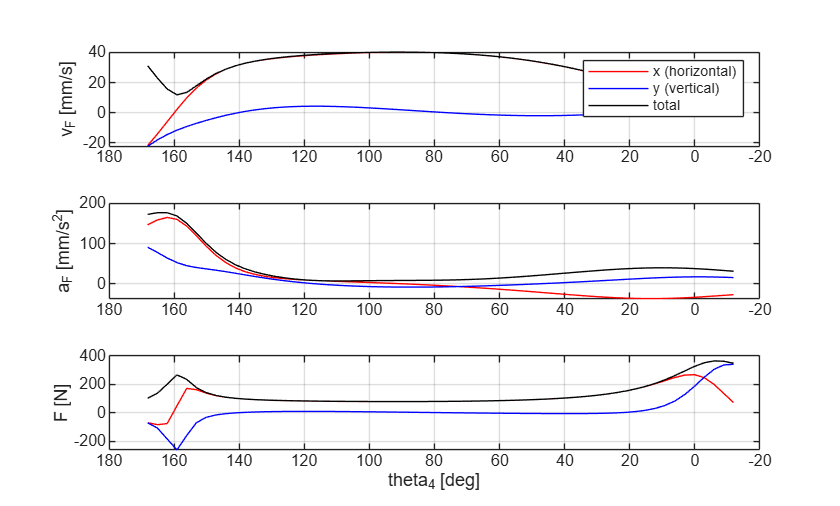

%ขาหน้า
dDx_f = diff(DxNew_f,theta4);   dDy_f = diff(DyNew_f,theta4);
dth_f = @(G) diff(G,theta4) + diff(G,Dxs)*dDx_f + diff(G,Dys)*dDy_f;
P_f   = [AxNew_f AyNew_f; Bx_f By_f; CxNew_f CyNew_f; DxNew_f DyNew_f; FxNew_f FyNew_f];
V_f   = dth_f(P_f)*omega4;
Acc_f = dth_f(V_f)*omega4;
th_deg_f = rad2deg(th_st_f);
vF_f   = [N_f(V_f(5,1),th_st_f); N_f(V_f(5,2),th_st_f)];
aF_f   = [N_f(Acc_f(5,1),th_st_f); N_f(Acc_f(5,2),th_st_f)];
vAbs_f = sqrt(vF_f(1,:).^2 + vF_f(2,:).^2);
aAbs_f = sqrt(aF_f(1,:).^2 + aF_f(2,:).^2);
FAbs_f = Torque*abs(omega4)./(vAbs_f/1000);
FF_f   = FAbs_f.*vF_f./vAbs_f;
figure
subplot(3,1,1); plot(th_deg_f,vF_f(1,:),"-r",th_deg_f,vF_f(2,:),"-b",th_deg_f,vAbs_f,"-k"); grid on; ylabel("v_F [mm/s]")
legend("x (horizontal)","y (vertical)","total")
subplot(3,1,2); plot(th_deg_f,aF_f(1,:),"-r",th_deg_f,aF_f(2,:),"-b",th_deg_f,aAbs_f,"-k"); grid on; ylabel("a_F [mm/s^2]")
subplot(3,1,3); plot(th_deg_f,FF_f(1,:),"-r",th_deg_f,FF_f(2,:),"-b",th_deg_f,FAbs_f,"-k"); grid on; ylabel("F [N]")
xlabel("theta_4 [deg]")
set(findall(gcf,"Type","axes"),"XDir","reverse")

th_deg_f = rad2deg(th_st_f);
Fx_st_f  = N_f(FxNew_f,th_st_f);
stroke_f = max(Fx_st_f) - min(Fx_st_f);
[~, iv_f] = max(abs(vF_f(1,:)));   max_vF_f = vF_f(1,iv_f);
[~, ia_f] = max(abs(aF_f(1,:)));   max_aF_f = aF_f(1,ia_f);
[min_F_f, iF_f] = min(FAbs_f);
theta_at_f = th_deg_f([iv_f ia_f iF_f]);
fprintf("FRONT leg\n")

FRONT leg


fprintf("stroke = %.2f mm\n", stroke_f)

stroke = 83.11 mm


fprintf("max_vFx, Deg = %.2f mm/s, %.2f deg\n", [max_vF_f, theta_at_f(1)])

max_vFx, Deg = 40.17 mm/s, 90.13 deg


fprintf("max_aFx, Deg = %.2f mm/s^2, %.2f deg\n", [max_aF_f, theta_at_f(2)])

max_aFx, Deg = 164.97 mm/s^2, 162.13 deg


fprintf("min_F, Deg = %.2f N, %.2f deg\n", [min_F_f, theta_at_f(3)])

min_F, Deg = 78.12 N, 90.13 deg


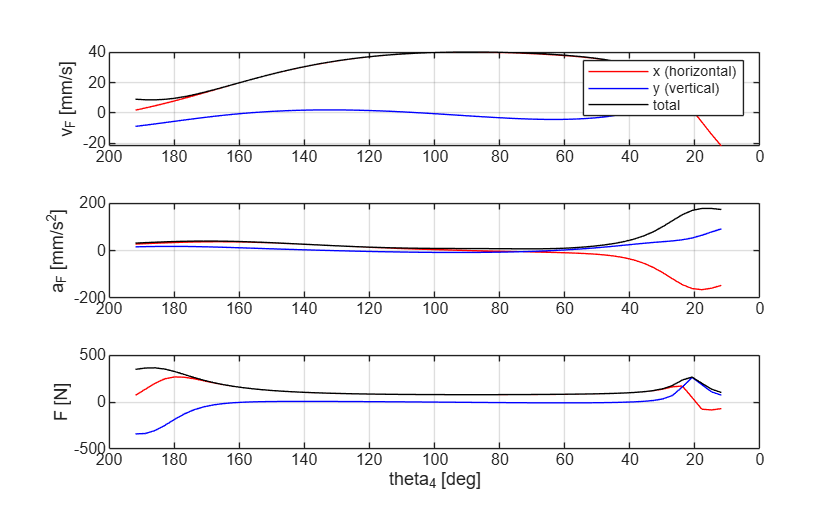

%ขาหลัง
dDx_r = diff(DxNew_r,theta4);   dDy_r = diff(DyNew_r,theta4);
dth_r = @(G) diff(G,theta4) + diff(G,Dxs)*dDx_r + diff(G,Dys)*dDy_r;
P_r   = [AxNew_r AyNew_r; Bx_r By_r; CxNew_r CyNew_r; DxNew_r DyNew_r; FxNew_r FyNew_r];
V_r   = dth_r(P_r)*omega4;
Acc_r = dth_r(V_r)*omega4;
th_deg_r = rad2deg(th_st_r);
vF_r   = [N_r(V_r(5,1),th_st_r); N_r(V_r(5,2),th_st_r)];
aF_r   = [N_r(Acc_r(5,1),th_st_r); N_r(Acc_r(5,2),th_st_r)];
vAbs_r = sqrt(vF_r(1,:).^2 + vF_r(2,:).^2);
aAbs_r = sqrt(aF_r(1,:).^2 + aF_r(2,:).^2);
FAbs_r = Torque*abs(omega4)./(vAbs_r/1000);
FF_r   = FAbs_r.*vF_r./vAbs_r;
figure
subplot(3,1,1); plot(th_deg_r,vF_r(1,:),"-r",th_deg_r,vF_r(2,:),"-b",th_deg_r,vAbs_r,"-k"); grid on; ylabel("v_F [mm/s]")
legend("x (horizontal)","y (vertical)","total")
subplot(3,1,2); plot(th_deg_r,aF_r(1,:),"-r",th_deg_r,aF_r(2,:),"-b",th_deg_r,aAbs_r,"-k"); grid on; ylabel("a_F [mm/s^2]")
subplot(3,1,3); plot(th_deg_r,FF_r(1,:),"-r",th_deg_r,FF_r(2,:),"-b",th_deg_r,FAbs_r,"-k"); grid on; ylabel("F [N]")
xlabel("theta_4 [deg]")
set(findall(gcf,"Type","axes"),"XDir","reverse")

th_deg_r = rad2deg(th_st_r);
Fx_st_r  = N_r(FxNew_r,th_st_r);
stroke_r = max(Fx_st_r) - min(Fx_st_r);
[~, iv_r] = max(abs(vF_r(1,:)));   max_vF_r = vF_r(1,iv_r);
[~, ia_r] = max(abs(aF_r(1,:)));   max_aF_r = aF_r(1,ia_r);
[min_F_r, iF_r] = min(FAbs_r);
theta_at_r = th_deg_r([iv_r ia_r iF_r]);
fprintf("REAR leg\n")

REAR leg


fprintf("stroke = %.2f mm\n", stroke_r)

stroke = 83.11 mm


fprintf("max_vFx, Deg = %.2f mm/s, %.2f deg\n", [max_vF_r, theta_at_r(1)])

max_vFx, Deg = 40.17 mm/s, 89.87 deg


fprintf("max_aFx, Deg = %.2f mm/s^2, %.2f deg\n", [max_aF_r, theta_at_r(2)])

max_aFx, Deg = -164.97 mm/s^2, 17.87 deg


fprintf("min_F, Deg = %.2f N, %.2f deg\n", [min_F_r, theta_at_r(3)])

min_F, Deg = 78.12 N, 89.87 deg
